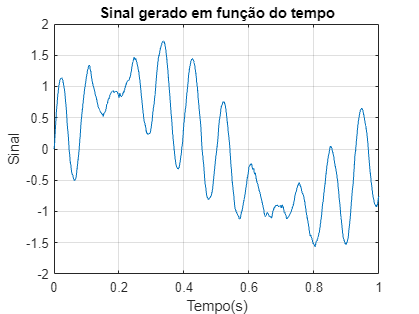

Ta = 0.001;
N = 1000;
[x,t] = GeraSinal(N,Ta);
figure
plot(t,x)
title('Sinal gerado em função do tempo')
xlabel('Tempo(s)')
ylabel('Sinal')
grid

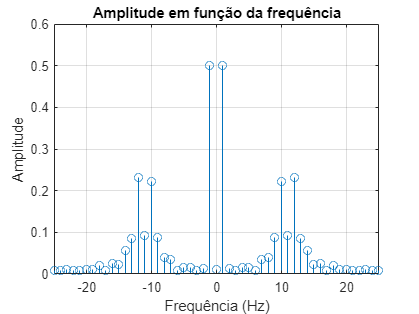


% 2.
[X,f] = Espetro(x,Ta);
xlim([-25,25])
grid

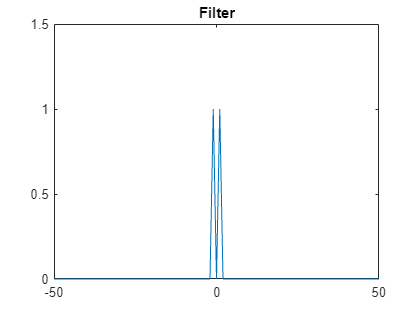


% 3.
filteredX = Filter(X,f,[0 2]);

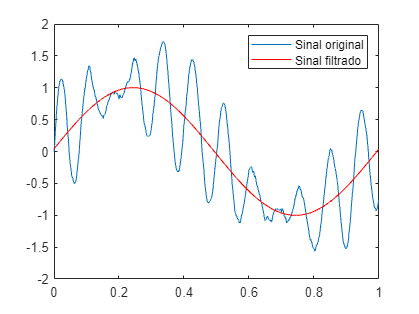


y = Reconstroi(filteredX,f);
figure
plot(t,x)
hold on
plot(t,y,'r-')
legend('Sinal original','Sinal filtrado')



% Função

function [x,t] = GeraSinal(N,Ta)
phi = normrnd(0,pi,[1,N]);
phi_i1 = zeros(1,N);
for n = 2:N
    phi_i1(n) = phi_i1(n-1) + (phi(n)+phi(n-1))*Ta/2;
end

phi = normrnd(0,pi,[1,N]);
phi_i2 = zeros(1,N);
for n = 2:N
    phi_i2(n) = phi_i2(n-1) + (phi(n)+phi(n-1))*Ta/2;
end

t = (0:N-1)*Ta;
x = sin(2*pi*t) + 0.5*sin(2*pi*10*t + 10*phi_i1) + 0.5*sin(2*pi*12*t + 10*phi_i2);
end